files = dir('/Users/kaustubhkanagalekar/dice_working_dir/MAE171a/results/*.txt'); % List all .txt files
num_files = length(files)-1;

num_points = 1384;
data_all = zeros(num_points, 12, num_files); % Preallocate for speed
%dir('/Users/kaustubhkanagalekar/dice_working_dir/MAE171a/results/DICe_solution_00.txt')

for i = 1:(num_files)
    file_path = fullfile('/Users/kaustubhkanagalekar/dice_working_dir/MAE171a/results', files(i).name);

    % Read the file and store the data
    data = readtable(file_path, 'Delimiter', ',', 'HeaderLines', 1); % Adjust headers if needed
    
    % Convert table to array and exclude SUBSET_ID
    data_all(:, :, i) = table2array(data(:, 2:end)); % Exclude SUBSET_ID


end



% testing bc idk
% mydata = data_all 
% strain_yy=mydata(:,12);
% xpos=mydata(:,2);
% ypos=mydata(:,3);
% figure(01)
% scatter(xpos,ypos,[],strain_yy,'filled')
% colorbar
% xlabel('x')
% ylabel('y')
% set(gca,'fontsize',20,'linewidth',2)


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%test 1 sample 1 
data2 = readmatrix('/Users/kaustubhkanagalekar/Desktop/Kaustubh MATLAB/test 1 W25 MAE 171A_sample_1.csv'); 
time = data2(:, 2); % Time column (in seconds)
displacement = data2(:, 3); % Displacement column (in mm)
force = data2(:, 4); % Force column (in N)

data2;
A= 50/1000 * 13/1000; %m^2 gauge area (gauge length*narrow width) 

A = 6.5000e-04

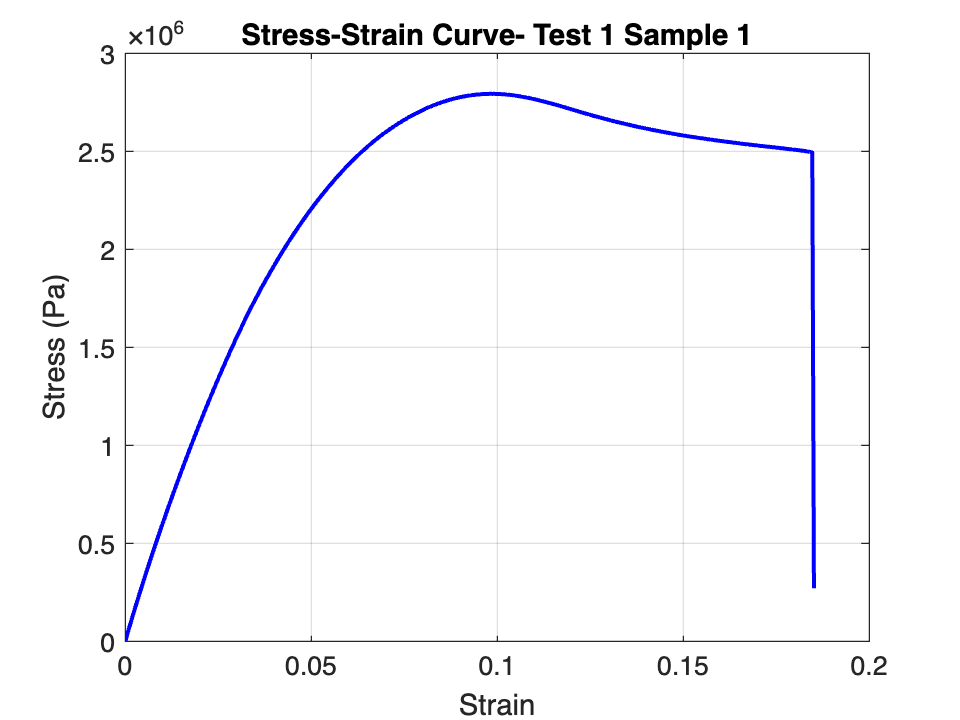

stress = force/A; %Pa

gauge_len = 50; %mm (original gauge length) 
strain = displacement/gauge_len;

figure(1);
plot(strain, stress, 'b-', 'LineWidth', 1.5);
ylabel('Stress (Pa)');
xlabel('Strain');
title('Stress-Strain Curve- Test 1 Sample 1');
grid on;


strain_limit = 0.02; %from visual inspection where linearity ends
el_ind = strain <= strain_limit; 
strain_new = strain(el_ind);
stress_new = stress(el_ind);
p = polyfit(strain_new, stress_new,1);
Elastic_mod_1 = p(1) %Pa

Elastic_mod_1 = 5.5251e+07


offset = 0.002;
strain_offset = strain; 
stress_offset = Elastic_mod*(strain_offset - offset);
diff = abs(stress - stress_offset); 
[~, yield_idx] = min(diff);
yield_strength_1 = stress(yield_idx) %Pa

yield_strength_1 = 1.5809e+06


ultimate_tensile_strength_1 = max(stress) %Pa

ultimate_tensile_strength_1 = 2.7934e+06

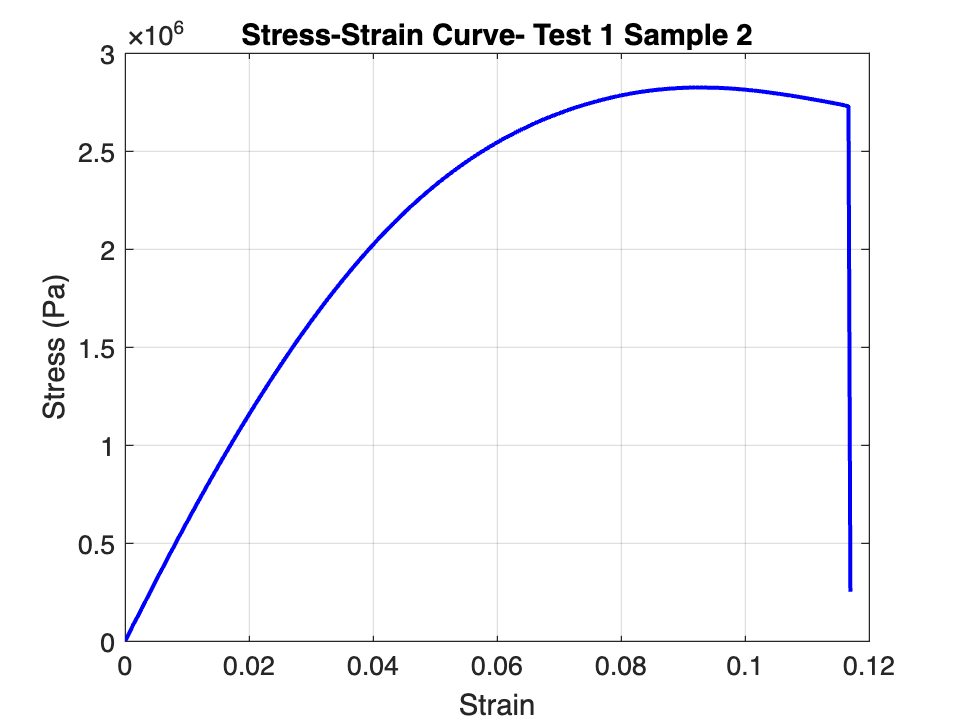

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% test 1 sample 2
data3 = readmatrix('/Users/kaustubhkanagalekar/Desktop/Kaustubh MATLAB/test 1 W25 MAE 171A_sample_2.csv'); 
time2 = data3(:, 2); % Time column (in seconds)
displacement2 = data3(:, 3); % Displacement column (in mm)
force2 = data3(:, 4); % Force column (in N)

data3;
A= 50/1000 * 13/1000; %m^2 gauge area (gauge length*narrow width) 
stress2 = force2/A; %Pa

gauge_len = 50; %mm (original gauge length) 
strain2 = displacement2/gauge_len;

figure(2);
plot(strain2, stress2, 'b-', 'LineWidth', 1.5);
ylabel('Stress (Pa)');
xlabel('Strain');
title('Stress-Strain Curve- Test 1 Sample 2');
grid on;


strain_limit = 0.02; %from visual inspection where linearity ends
el_ind = strain2 <= strain_limit; 
strain_new2 = strain2(el_ind);
stress_new2 = stress2(el_ind);
p = polyfit(strain_new2, stress_new2,1);
Elastic_mod_2 = p(1) %Pa

Elastic_mod_2 = 5.8023e+07


offset = 0.002;
strain_offset_2 = strain2; 
stress_offset_2 = Elastic_mod_2*(strain_offset_2 - offset);
diff2 = abs(stress2 - stress_offset_2); 
[~, yield_idx2] = min(diff2);
yield_strength_2 = stress(yield_idx2) %Pa

yield_strength_2 = 1.5265e+06


ultimate_tensile_strength_2 = max(stress2) %Pa

ultimate_tensile_strength_2 = 2.8256e+06

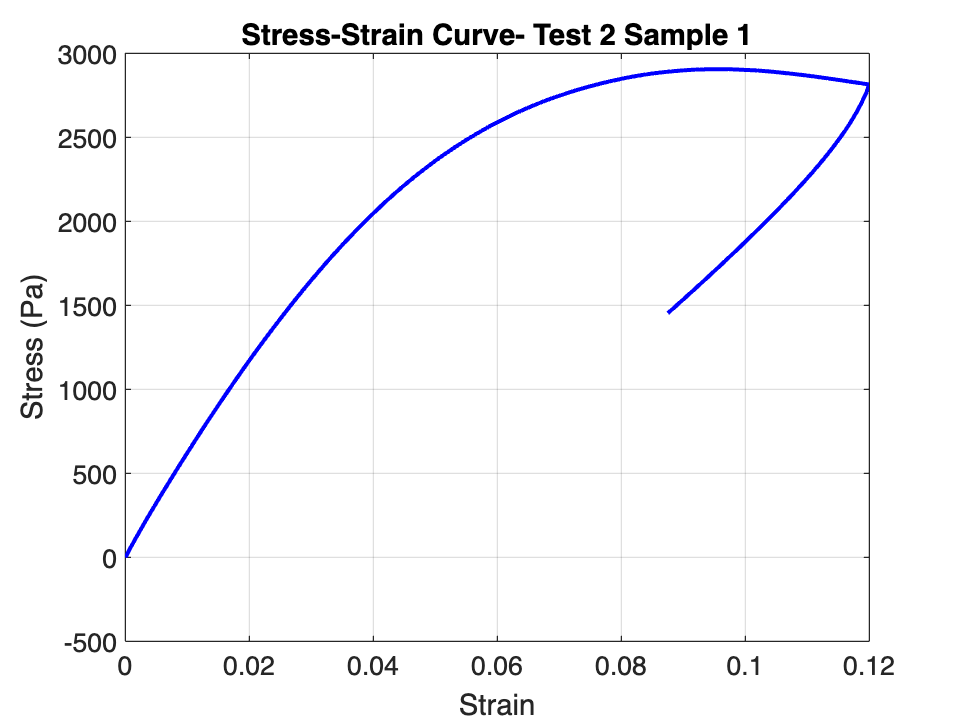

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
%test 1 sample 2 
data4 = readmatrix('/Users/kaustubhkanagalekar/Desktop/Kaustubh MATLAB/test 2 W25 MAE 171A_sample_1.csv'); 

time3 = data4(:, 1); % Time column (in seconds)
displacement3 = data4(:, 2); % Displacement column (in mm)
force3 = data4(:, 3); % Force column (in N)

data4;
A= 50/1000 * 13/1000; %m^2 gauge area (gauge length*narrow width) 
stress3 = force3/A; %Pa

gauge_len = 50; %mm (original gauge length) 
strain3 = displacement3/gauge_len;

figure(3);
plot(strain3, stress3, 'b-', 'LineWidth', 1.5);
ylabel('Stress (Pa)');
xlabel('Strain');
title('Stress-Strain Curve- Test 2 Sample 1');
grid on;


strain_limit = 0.02; %from visual inspection where linearity ends
el_ind = strain3 <= strain_limit; 
strain_new3 = strain3(el_ind);
stress_new3 = stress3(el_ind);
p = polyfit(strain_new3, stress_new3,1);
Elastic_mod_3 = p(1) %Pa

Elastic_mod_3 = 5.8349e+04


offset = 0.002;
strain_offset_3 = strain3; 
stress_offset_3 = Elastic_mod_3*(strain_offset_3 - offset);
diff3 = abs(stress3 - stress_offset_3); 
[~, yield_idx3] = min(diff3);
yield_strength_3 = stress(yield_idx3) %Pa

yield_strength_3 = 1.4991e+06


ultimate_tensile_strength_3 = max(stress3) %Pa

ultimate_tensile_strength_3 = 2.9058e+03